# Manipulation Estimation and Controls: Assignment 2

Submitted by: Sushanth Jayanth

## Q1. Given open loop transfer function

G = tf(200, [1 22 141 2])

G =
 
            200
  ------------------------
  s^3 + 22 s^2 + 141 s + 2
 
Continuous-time transfer function.



#### a. Closed loop transfer function with unity feedback (assumig negative feedback)

sys1 = feedback(G,1)

sys1 =
 
             200
  --------------------------
  s^3 + 22 s^2 + 141 s + 202
 
Continuous-time transfer function.



#### b. Poles and Zeros of closed loop transfer function

The poles are shown below, but the system has no zeros

[zeros, poles, gains] = tf2zp(200,[1 22 141 202])


zeros =

  0×1 empty double column vector



poles =  -10.0000 + 1.0000i
 -10.0000 - 1.0000i
  -2.0000 + 0.0000i


gains = 200

#### c. Plot y(t) using step function

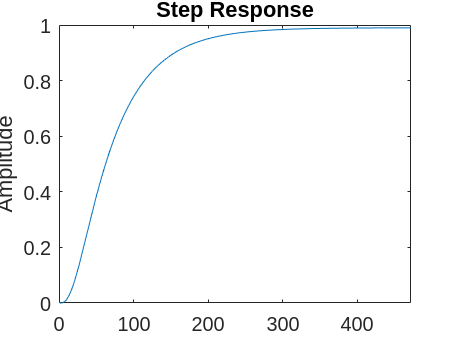

y = step(sys1);
plot(y)
title('Step Response')
ylabel('Amplitude')
xlabel('time')

Plotting the poles of the system

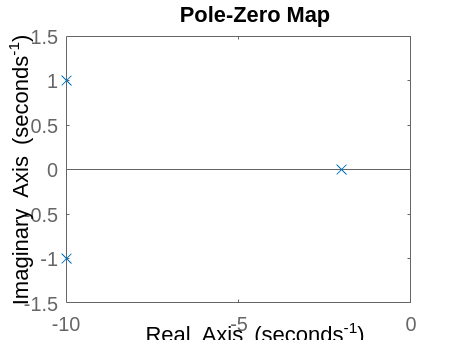

pzplot(sys1)

The pole at (-2 ± 0i) is dominant since it's closer to the imaginary axis. Also the poles at (-10 ± i) do not seem to be causing any oscillations and are therefore not dominant.

#### d. Steady state value using final value theorem

It is found below that the steady state value = 0.99

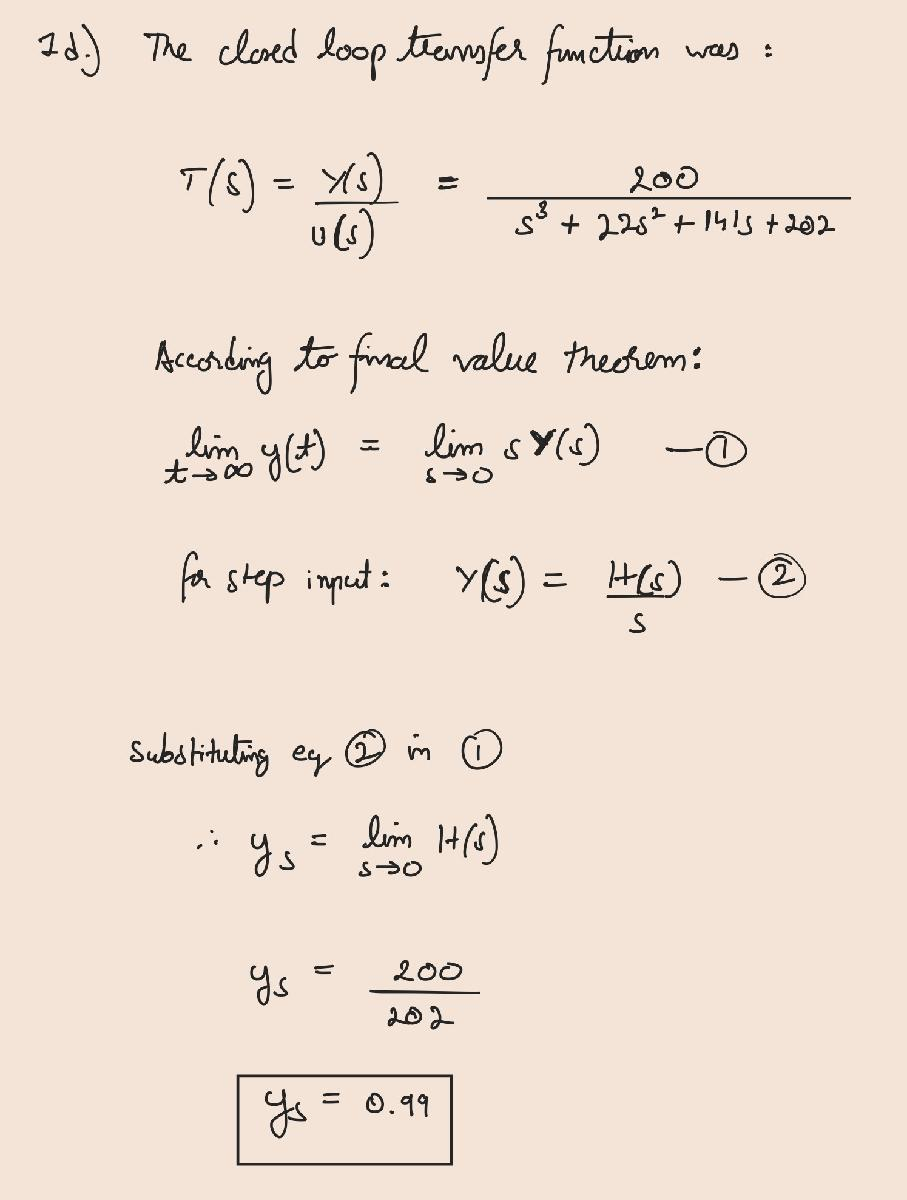

## Q2. Implementation of PID Controller

Given Transfer function:

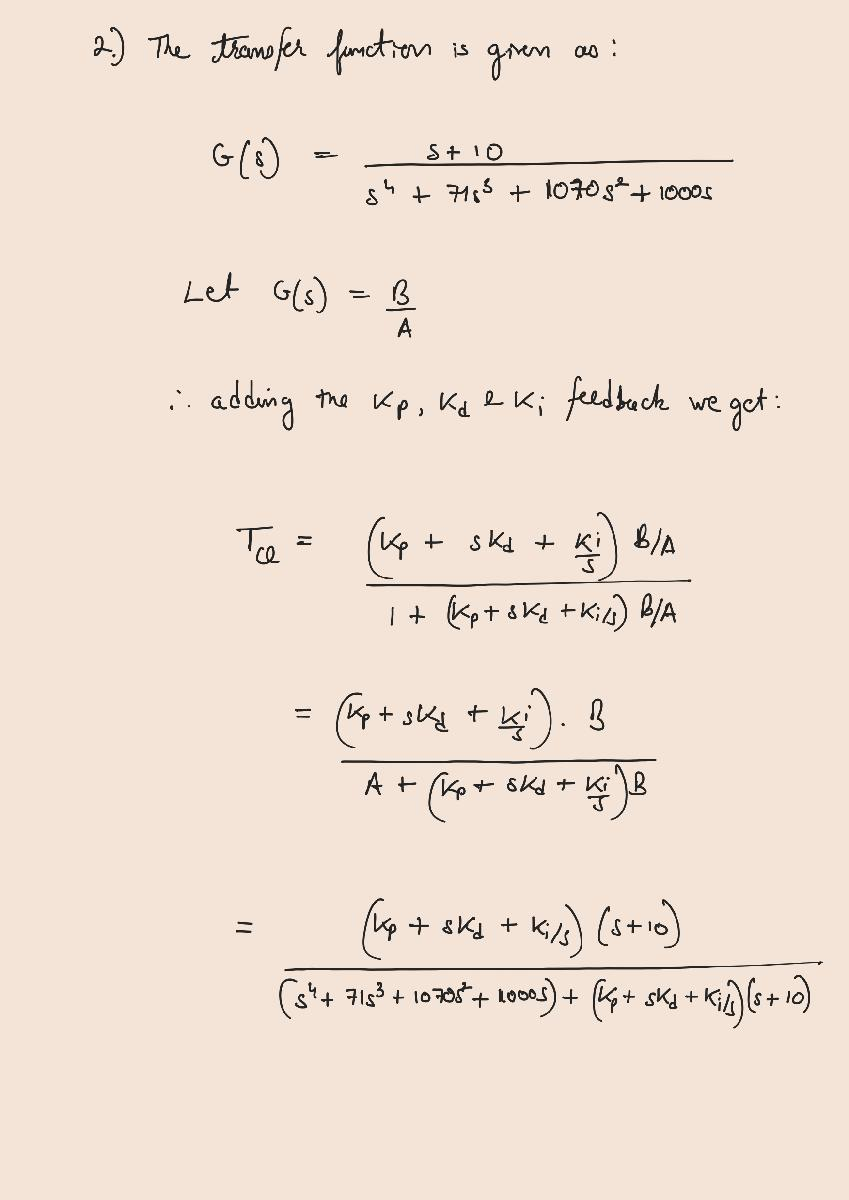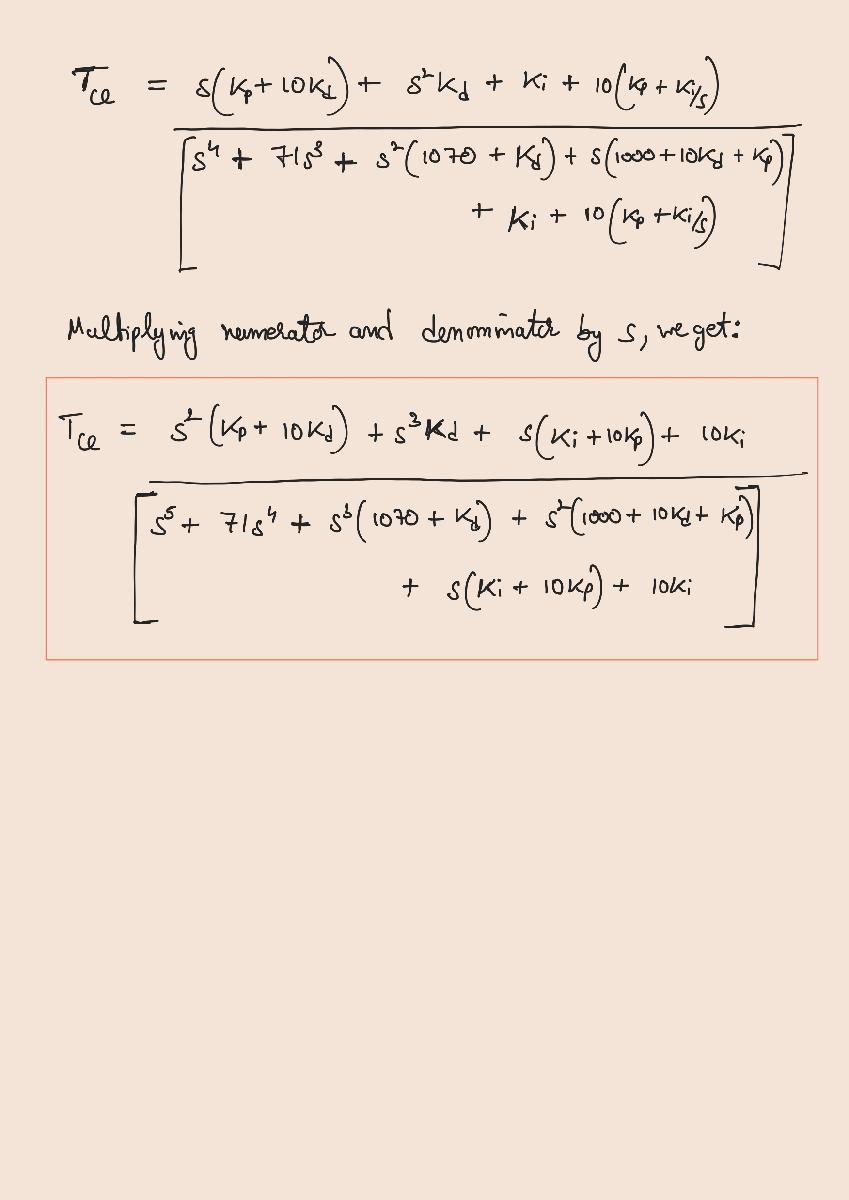

The PID controller was tuned using the below mentioned gains.

- Rise Time = 0.397s

- Maximum Percent Overshoot = 0.07

Kp = 600;
Kd = 590;
Ki = 4.7;

Plotting the step response and calculating the steady-state error:

G2 = tf([Kd, Kp+10*Kd, Ki+10*Kp, 10*Ki],[1, 71, 1070+Kd, 1000+10*Kd+Kp, Ki+10*Kp, 10*Ki])

G2 =
 
          590 s^3 + 6500 s^2 + 6005 s + 47
  ------------------------------------------------
  s^5 + 71 s^4 + 1660 s^3 + 7500 s^2 + 6005 s + 47
 
Continuous-time transfer function.



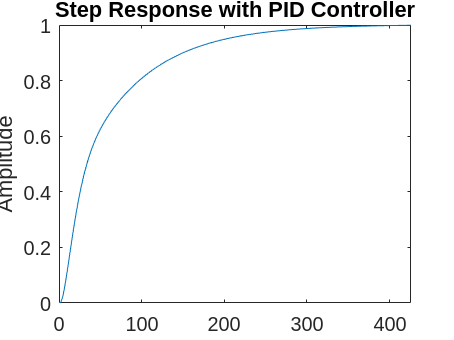

y2 = step(G2);
plot(y2)
title('Step Response with PID Controller')
ylabel('Amplitude')
xlabel('time (s)')


stepinfo(G2)

ans = struct with fields:
         RiseTime: 0.3965
    TransientTime: 0.7538
     SettlingTime: 0.7538
      SettlingMin: 0.9013
      SettlingMax: 1.0007
        Overshoot: 0.0737
       Undershoot: 0
             Peak: 1.0007
         PeakTime: 1.4050



% Find the steady state error
% expected step output is 1
y2(end)

ans = 0.9990

std_state_error = 1 - y2(end)

std_state_error = 9.5398e-04

## Q3. Observer for Cart Pendulum System

The tracking controller in Problem 2(h) in Problem Set 1 was shown as:

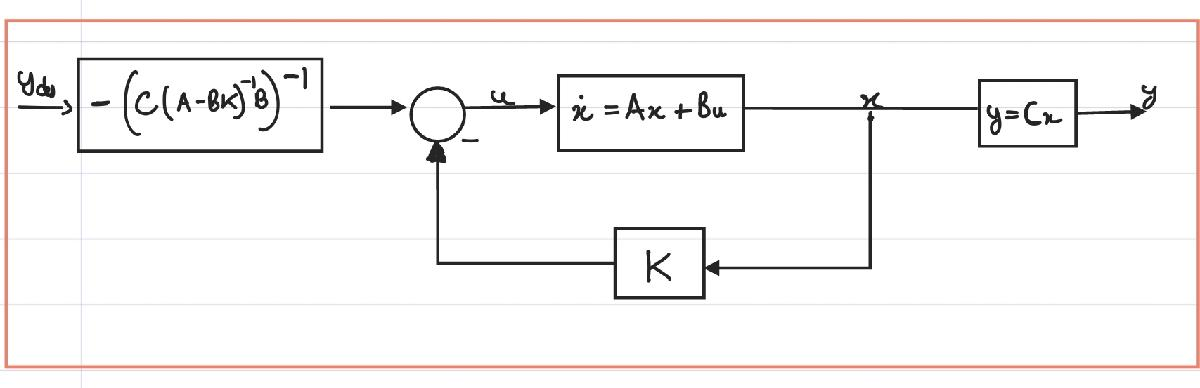

Now, along with an observer, the system can be shown as:

The system variables for the inverted cart pendulum model were

% Define the system variables:
A = [[0,0,1,0];[0,0,0,1];[0,1,-3,0];[0,2,-3,0]]

A =      0     0     1     0
     0     0     0     1
     0     1    -3     0
     0     2    -3     0



B = [0;0;1;1]

B =      0
     0
     1
     1


C = [39.3701, 0, 0, 0]

C =    39.3701         0         0         0



% Find the optimal feedback gain
Q = [[20,0,0,0];[0,5,0,0];[0,0,1,0];[0,0,0,5]];
R = 20;
K = lqr(A, B, Q, R)

K =    -1.0000   12.0469   -8.3985   11.0015


We need to keep the observer poles far left of the controller poles, i.e. around 4x further (since the observer poles should be computed faster and should not have much effect on the controller)

% Find the K0 values for observer
controller_poles = eig(A-B*K)

controller_poles =    -3.3650
   -1.1261
   -0.7684
   -0.3434



% Based on the position of controller poles, the observer poles are places
% as shown
observer_poles = [-3, -2.2, -2, -2.5]

observer_poles =    -3.0000   -2.2000   -2.0000   -2.5000



% Calculating the error term K_0
K_tmp = place(transpose(A), transpose(C), observer_poles);
K_0 = transpose(K_tmp)

K_0 =     0.1702
    1.8313
    0.4293
    2.2073


% Defining the timespan for the whole system
t_1 = 0 : 0.01 : 200;

% define parameters for y_des only for plotting
freq=0.01;
offset=0;
amp=20;
duty=50;

% define y_des as a square wave function
y_des = offset+amp*square(2*pi*freq.*t_1,duty);

v = -1 * inv(C*inv((A-B*K))*B);

controller_tracker = [];
observer_tracker = [];

count = 0;
for timespan=0:0.01:200
    if count == 0
        x_1 = [0; 0; 0; 0];
        x_hat = [0; 0; 0; 0];
    else
        x_1 = carry_over_1_last;
        x_hat = carry_over_2_last;
    end
    % controller
    [t1,x1] = ode45(@(t1,x1)(tracking_controller(x1, -K*x_hat, v, timespan)), [0,0.01], x_1);
    carry_over_1 = transpose(x1);
    carry_over_1_last = carry_over_1(:,end);
    controller_tracker = vertcat(controller_tracker, transpose(carry_over_1_last));

    if count == 0
        x_2 = [0; 0; 0; 0];
    else
        x_2 = carry_over_2_last;
    end

    % observer
    [t2,x2] = ode45(@(t1,x2)(tracking_controller_observer(x2, K, v, timespan, K_0, carry_over_1_last, C)), [0,0.01], x_2);
    carry_over_2 = transpose(x2);
    carry_over_2_last = carry_over_2(:,end);
    observer_tracker = vertcat(observer_tracker, transpose(carry_over_2_last));
    count = count + 1;
end

Plot only the position state w.r.t time

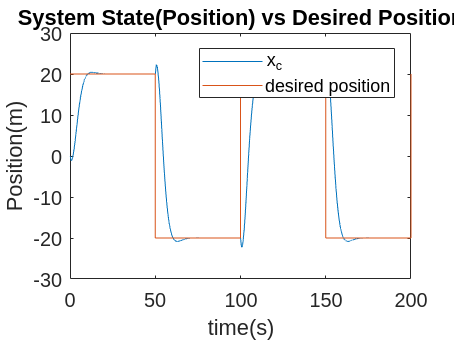

controller_tracker_position = controller_tracker(:,1)*39.3701;
% Plot of controller output against desired output
plot(t_1, controller_tracker_position)
hold on
plot(t_1,y_des)
hold off
title('System State(Position) vs Desired Position')
ylabel('Position(m)')
xlabel('time(s)')
legend({'x_c', 'desired position'})

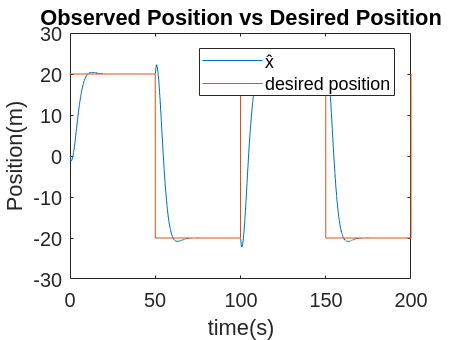

observer_tracker_position = observer_tracker(:,1)*39.3701;
% Plot of observer output against desired output
plot(t_1, observer_tracker_position)
hold on
plot(t_1,y_des)
hold off
title('Observed Position vs Desired Position')
ylabel('Position(m)')
xlabel('time(s)')
legend({'x̂', 'desired position'})

Controller System States vs Observer Estimates

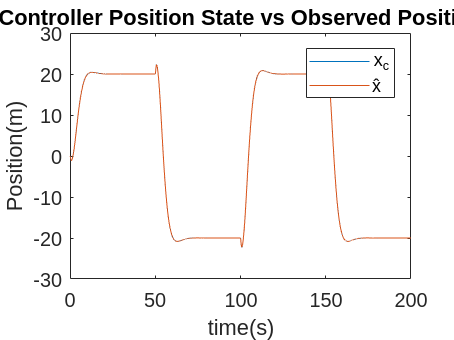

% Plot of observer output against desired output
plot(t_1, controller_tracker_position)
hold on
plot(t_1, observer_tracker_position)
hold off
title('Controller Position State vs Observed Position')
ylabel('Position(m)')
xlabel('time(s)')
legend({'x_c', 'x̂'})

Error Plot: Controller System State (position) - Observer Estimate of Position

% Find the max error between the two plots
max_error = max(abs(controller_tracker_position - observer_tracker_position))

max_error = 0.0396

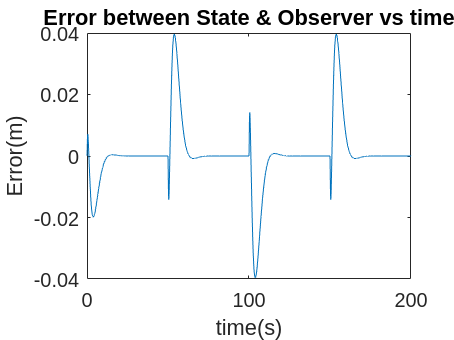

% Plot the error over time
controller_observer_error = controller_tracker_position - observer_tracker_position;
plot(t_1, controller_observer_error)
title('Error between State & Observer vs time')
ylabel('Error(m)')
xlabel('time(s)')

Plotting the controller states vs time

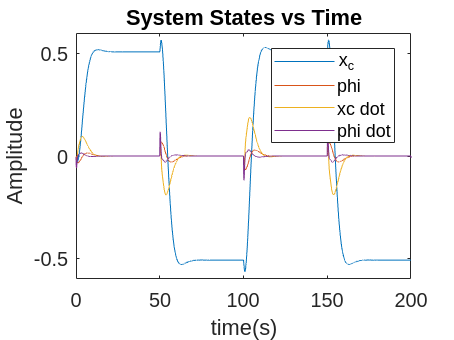

controller_tracker(:,1) = controller_tracker(:,1);
% Plot of controller state outputs
plot(t_1, controller_tracker)
title('System States vs Time')
ylabel('Amplitude')
xlabel('time(s)')
legend({'x_c', 'phi','xc dot', 'phi dot'})

Plotting the observer state estimates vs time

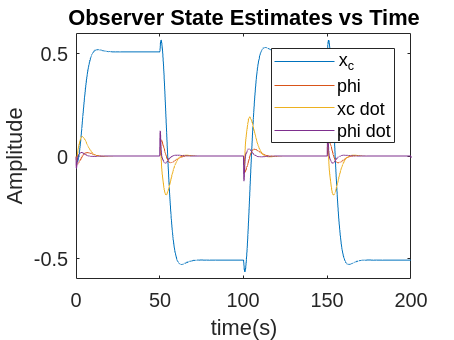

observer_tracker(:,1) = observer_tracker(:,1);
% Plot of controller state outputs
plot(t_1, observer_tracker)
title('Observer State Estimates vs Time')
ylabel('Amplitude')
xlabel('time(s)')
legend({'x_c', 'phi','xc dot', 'phi dot'})

Helper function for controller ODE45

function x_dot = tracking_controller (x, F, v, t)
xc = x(1);
phi = x(2);
xcdot = x(3);
phidot = x(4);

% constants in the system
gamma = 2;
alpha = 1;
beta = 1;
D = 1;
mu = 3;

% define parameters for y_des
freq=0.01;
offset=0;
amp=20;
duty=50;

% define y_des as a square wave function
y_des = offset+amp*square(2*pi*freq.*t,duty);
u = F + v*y_des;

divisor = ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)))^(-1);

x_dot = [xcdot;
        phidot;
        divisor*((u*alpha) - (beta*phidot*phidot*sin(phi)*alpha) - (alpha*mu*xcdot) + (beta*D*sin(phi)*cos(phi)));
        divisor*((u*beta*cos(phi)) - (beta*beta*phidot*phidot*sin(phi)*cos(phi)) - (beta*cos(phi)*mu*xcdot) + (gamma*D*sin(phi)))];


% divisor_1 = alpha / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));
% divisor_2 = (beta*cos(phi)) / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));

% x_dot = [xcdot;
%        phidot;
%        divisor_1*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((beta*D*cos(phi)*sin(phi))/alpha));
%        divisor_2*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((gamma*D*sin(phi)) / (beta*cos(phi))))];

end

Helper function for observer ODE45

function x_dot = tracking_controller_observer (x, K, v, t, K_0, controller_op, C)
xc = x(1);
phi = x(2);
xcdot = x(3);
phidot = x(4);

% constants in the system
gamma = 2;
alpha = 1;
beta = 1;
D = 1;
mu = 3;

% define parameters for y_des
freq=0.01;
offset=0;
amp=20;
duty=50;

% define y_des as a square wave function
y_des = offset+amp*square(2*pi*freq.*t,duty);
u = -K*x + v*y_des;

divisor = ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)))^(-1);

x_dot = [xcdot;
        phidot;
        divisor*((u*alpha) - (beta*phidot*phidot*sin(phi)*alpha) - (alpha*mu*xcdot) + (beta*D*sin(phi)*cos(phi)));
        divisor*((u*beta*cos(phi)) - (beta*beta*phidot*phidot*sin(phi)*cos(phi)) - (beta*cos(phi)*mu*xcdot) + (gamma*D*sin(phi)))];

error = K_0*(C*controller_op - C*x);
x_dot = x_dot + error;
% divisor_1 = alpha / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));
% divisor_2 = (beta*cos(phi)) / ((gamma*alpha) - (beta*beta*cos(phi)*cos(phi)));

% x_dot = [xcdot;
%        phidot;
%        divisor_1*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((beta*D*cos(phi)*sin(phi))/alpha));
%        divisor_2*(u - (beta*phidot*phidot*sin(phi)) - (mu*xcdot) + ((gamma*D*sin(phi)) / (beta*cos(phi))))];

end